# Analyze more examples using collected data

## Kobe earthquake data: Frequency-Localized Reconstruction from the Continuous Wavelet Transform

Reconstruct a frequency-localized approximation of the Kobe earthquake data. The data is sampled at 1 Hz. Extract information from the CWT for frequencies in the range of [0.030, 0.070] Hz.

load kobe
Fs = 1;

Obtain the CWT of the data.

[wt,f] = cwt(kobe,Fs);

Reconstruct the earthquake data, adding the signal mean back into the transformed data.

xrec = icwt(wt,[],f,[0.030 0.070],SignalMean=mean(kobe));

Plot and compare the original data and the data for frequencies in the range of [0.030, 0.070] Hz.

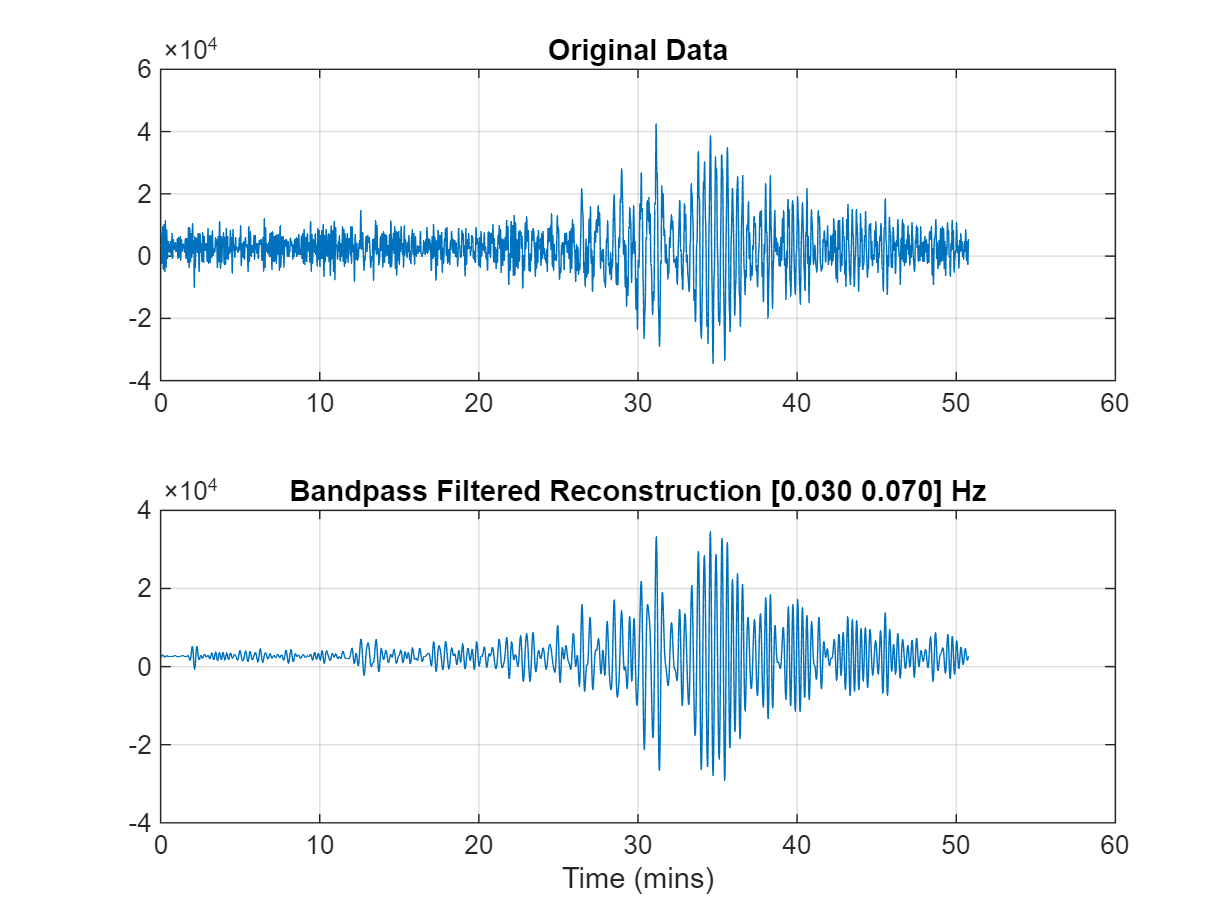

t = (0:numel(kobe)-1)/60;
tiledlayout(2,1)
nexttile
plot(t,kobe)
grid on
title("Original Data")
nexttile
plot(t,xrec)
grid on
xlabel("Time (mins)")
title("Bandpass Filtered Reconstruction [0.030 0.070] Hz")

## Bat data: Echolocation Pulse

Load a datafile containing an echolocation pulse emitted by a big brown bat (*Eptesicus fuscus*) and measured with a sample rate of 7 microseconds. 

load batsignal
Fs = 1/DT;

Compute the reassigned spectrogram of the signal.

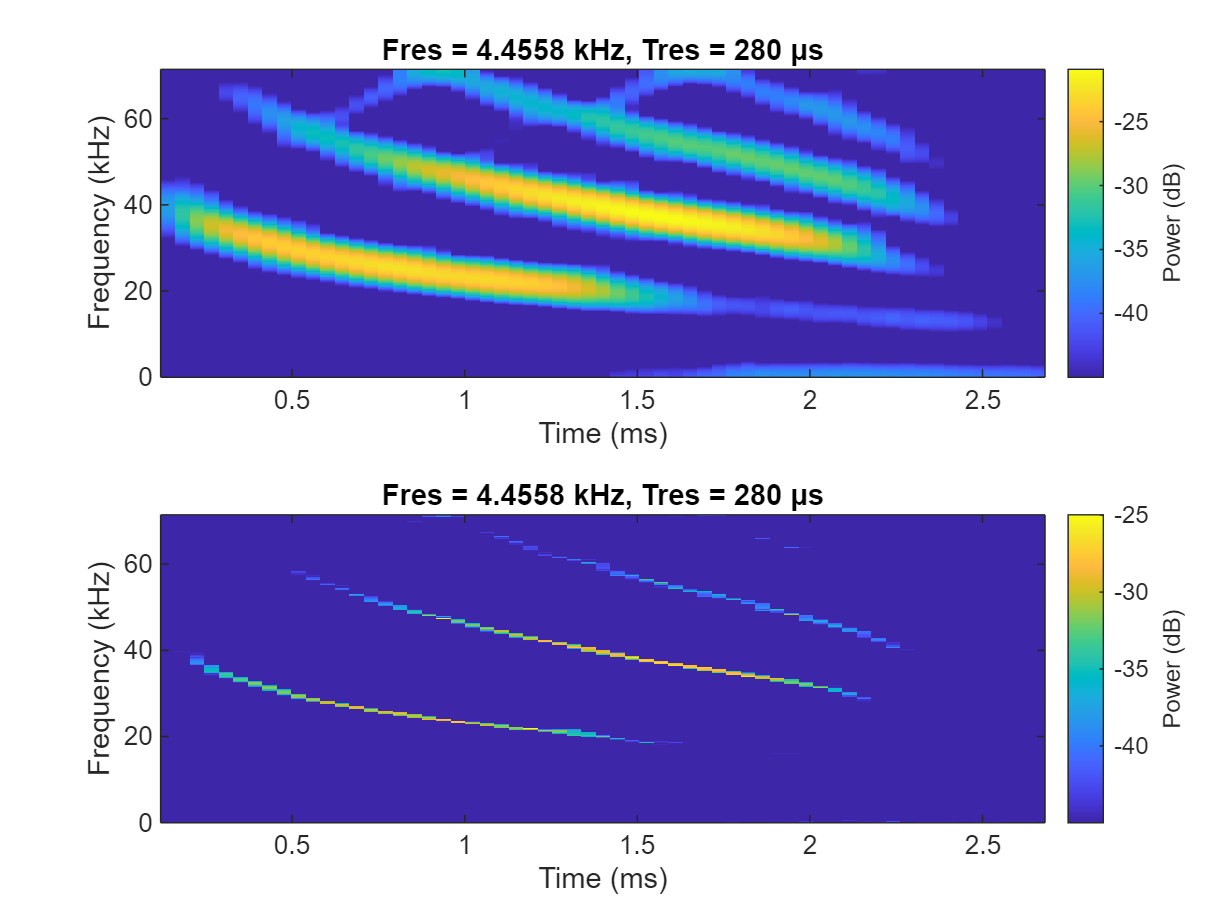

colormap parula; % or sky
tiledlayout(2,1)
nexttile
pspectrum(batsignal,Fs,"spectrogram", ...
    TimeResolution=280e-6, ...
    OverlapPercent=85, ...
    MinThreshold=-45, ...
    Leakage=0.9)
nexttile
pspectrum(batsignal,Fs,"spectrogram", ...
    TimeResolution=280e-6, ...
    OverlapPercent=85, ...
    MinThreshold=-45, ...
    Leakage=0.9, ...
    Reassign=true)